clc
clear all
close all

s = tf('s');

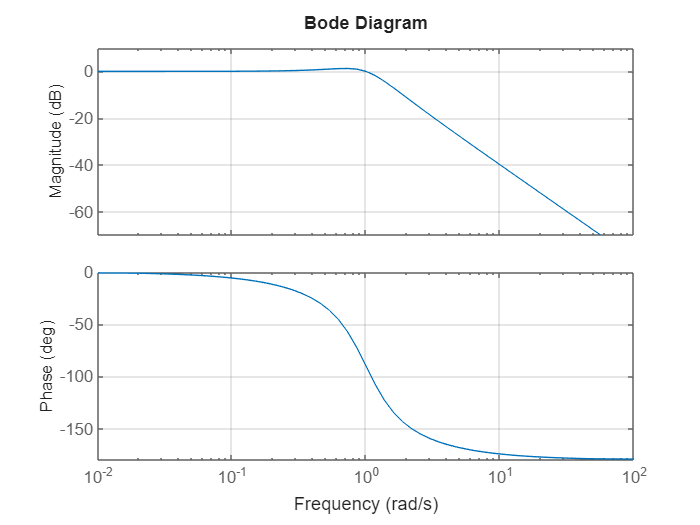

G = 1/(s^2+s+1);
K0 = 100;
Cb = 2.11*(s+4.74)/(s+21.08);
C = K0*Cb;

bode(G)
grid on

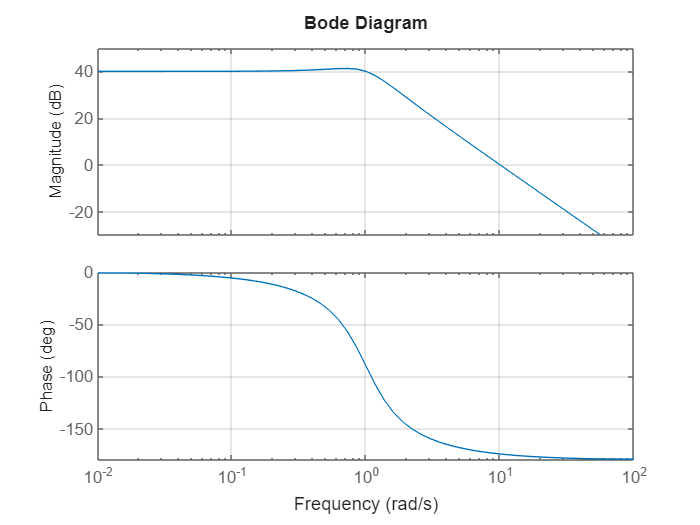

bode(K0*G)
grid on

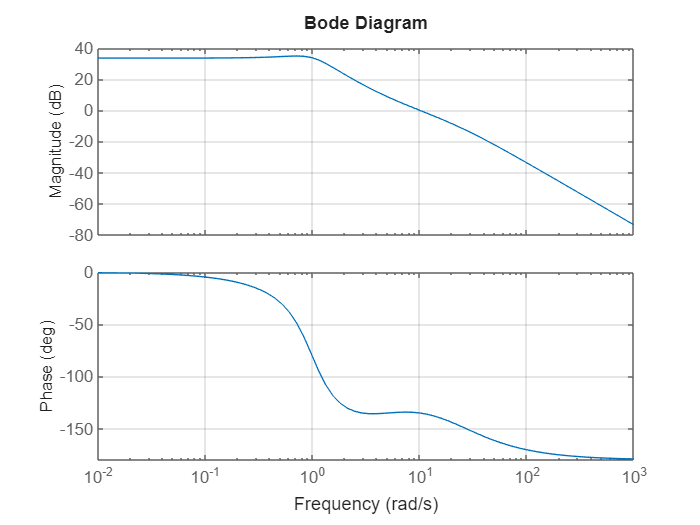

bode(C*G)
grid on

Para a mesma planta Projetar compensador de ganho, avanço e atraso de forma que: - 9 <= wodb <= 11 - 40 <= margem fase <= 50 - ep <= 0.1%

% Analise inicial (wodb, margem_fase, Kp)
bode(G)
grid on


wodb = 1;
margem_fase = 90;
Kp = 1; % Ganho em baixa frequencia (0db)

% Projeto Ganho (p/ ajustar wodb)

K0 = 10 ^(40/20) % Ganho da frequencia alvo

K0 = 100

Kp_ganho = Kp * K0

Kp_ganho = 100

wodb_novo = 10;
bode(Kp_ganho*G)
grid on

margem_fase = 5.75;

% Projeto Avanço (p/ ajustar margem_fase)
% Kp_avanco = Kp_ganho/Kb; 

margem_fase_alvo = 45;
margem_final = margem_fase_alvo - margem_fase + 5 % 5 é do compensador de atraso 

margem_final = 44.2500

beta = (1 + sind(margem_final))/(1-sind(margem_final))

beta = 5.6179

Pb = wodb_novo*sqrt(beta)

Pb = 23.7022

zb = Pb/beta

zb = 4.2190

Kb = sqrt(beta)

Kb = 2.3702


Cs = K0*(Kb*(s+zb)/(s+Pb))


Cs =
 
  237 s + 1000
  ------------
    s + 23.7
 
Continuous-time transfer function.
Model Properties


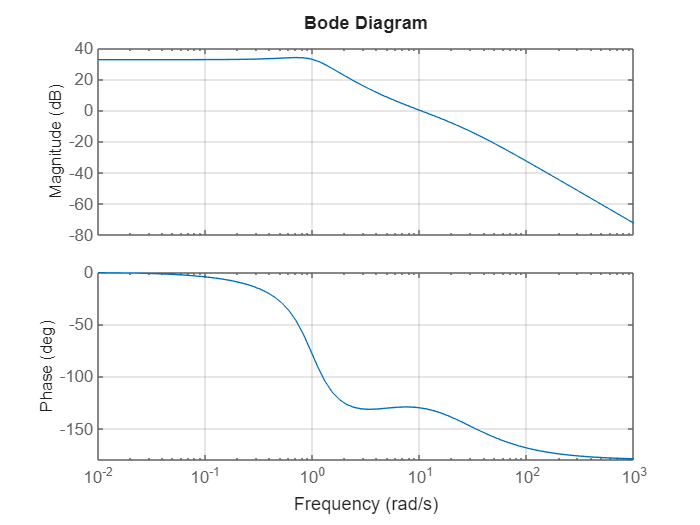


bode(Cs*G)
grid on

Kp_avanco = Kp_ganho/Kb 

Kp_avanco = 42.1902

% Projetar Atraso (p/ ajustar Kp)

erro = 0.1 / 100;
Kp_alvo = (1/erro)-1

Kp_alvo = 999

alpha = Kp_alvo / Kp_avanco

alpha = 23.6785

za = wodb_novo/10

za = 1

pa = za/alpha

pa = 0.0422

Cs = K0 * ((s+za)/(s+pa)) * (Kb*(s+zb)/(s+Pb))


Cs =
 
  237 s^2 + 1237 s + 1000
  -----------------------
   s^2 + 23.74 s + 1.001
 
Continuous-time transfer function.
Model Properties


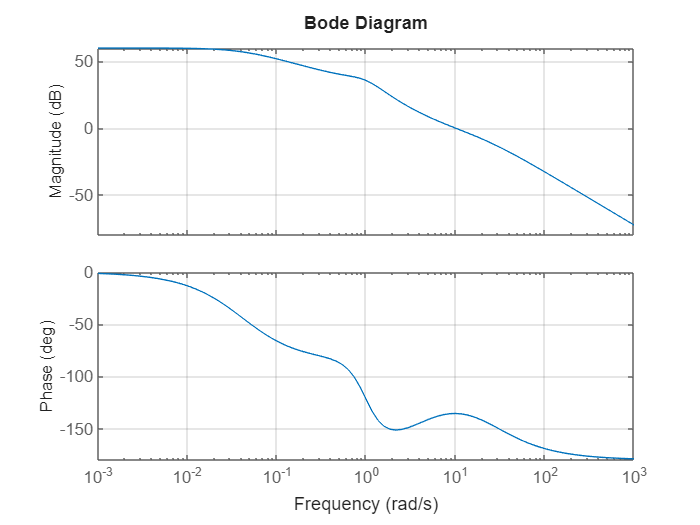

bode(Cs*G)
grid on